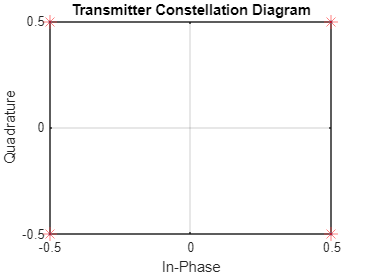

% IEEE 802.11n Wireless Voice Transmitter
% Parameters Setup
fs = 44100;          % Sampling frequency
channelBW = 20e6;    % Channel bandwidth (20 MHz)
fc = 2.4e9;          % Carrier frequency (2.4 GHz)
txPower = 0.5;       % Transmit power in Watts

% Load binary voice file
fileID = fopen('voice.bin', 'rb');
binData = fread(fileID, 'uint8');
fclose(fileID);

% Convert to binary stream (manual conversion)
binStream = zeros(1, length(binData) * 8);
for i = 1:length(binData)
    byte = binData(i);
    for j = 1:8
        binStream((i-1)*8 + j) = bitget(byte, 9-j);
    end
end

% Frame the data according to 802.11n
frameSize = 1024;  % Size of each frame
numFrames = ceil(length(binStream)/frameSize);
paddedData = [binStream zeros(1, numFrames*frameSize - length(binStream))];
frames = reshape(paddedData, frameSize, numFrames)';

% QPSK Modulation
symbolMapping = [-1-1i, -1+1i, 1-1i, 1+1i]/sqrt(2);  % QPSK constellation
bitsPerSymbol = 2;
modData = zeros(numFrames, frameSize/bitsPerSymbol);

% Symbol mapping
for i = 1:numFrames
    for j = 1:frameSize/bitsPerSymbol
        bits = frames(i, (j-1)*bitsPerSymbol + 1 : j*bitsPerSymbol);
        symbolIndex = bits(1)*2 + bits(2) + 1;
        modData(i,j) = symbolMapping(symbolIndex);
    end
end

% Apply transmit power scaling
txSignal = sqrt(txPower) * modData;

% Save transmitted signal
save('tx_signal.mat', 'txSignal', 'fs', 'fc', 'frameSize', ...
    'symbolMapping', 'bitsPerSymbol', 'binStream');

% Plot transmission constellation
figure('Name', 'Transmitter Constellation');
plot(real(txSignal(:)), imag(txSignal(:)), '.');
hold on;
plot(real(symbolMapping)*sqrt(txPower), imag(symbolMapping)*sqrt(txPower), 'r*', 'MarkerSize', 10);
title('Transmitter Constellation Diagram');
xlabel('In-Phase');
ylabel('Quadrature');
grid on;


% Display transmission parameters
fprintf('Transmission Parameters:\n');

Transmission Parameters:


fprintf('Carrier Frequency: %.2f GHz\n', fc/1e9);

Carrier Frequency: 2.40 GHz


fprintf('Sampling Rate: %.2f kHz\n', fs/1e3);

Sampling Rate: 44.10 kHz


fprintf('Transmit Power: %.2f W\n', txPower);

Transmit Power: 0.50 W


fprintf('Frame Size: %d bits\n', frameSize);

Frame Size: 1024 bits


fprintf('Number of Frames: %d\n', numFrames);

Number of Frames: 69


% IEEE 802.11n Wireless Voice Receiver
% Load transmitted signal
load('tx_signal.mat');  % Contains txSignal, fs, fc, frameSize, symbolMapping, bitsPerSymbol, binStream

% Channel Parameters
distance = 10;       % Distance in meters
pathLossExp = 2;     % Path loss exponent
shadowingStd = 8;    % Shadowing standard deviation in dB

% Calculate path loss
pathLoss = 20*log10(distance) + 20*log10(4*pi*fc/3e8);
pathLossLinear = 10^(-pathLoss/20);

% Apply shadowing
shadowing = 10^(normrnd(0, shadowingStd)/20);

% Setup Rayleigh channel
pathDelays = [0 50 150 250]*1e-9;  % Delays in seconds
pathGains = [0 -3 -10 -15];        % Path gains in dB

rayleighChan = comm.RayleighChannel(...
    'SampleRate', fs, ...
    'PathDelays', pathDelays, ...
    'AveragePathGains', pathGains, ...
    'MaximumDopplerShift', 0, ...
    'PathGainsOutputPort', true);

% Process received signal
[numFrames, frameLen] = size(txSignal);
rxSignal = zeros(size(txSignal));

% Apply channel effects
for i = 1:numFrames
    % Apply path loss and shadowing
    sigWithLoss = txSignal(i,:) * pathLossLinear * shadowing;
    
    % Apply multipath using RayleighChannel
    [sigWithMultipath, pathGainsOut] = rayleighChan(sigWithLoss.');
    
    % Add thermal noise
    noiseVar = 1e-12;  % Thermal noise variance
    noise = sqrt(noiseVar/2)*(randn(size(sigWithMultipath)) + 1i*randn(size(sigWithMultipath)));
    rxSignal(i,:) = (sigWithMultipath + noise).';
end

% Reset channel
reset(rayleighChan);

% Receiver Processing
rxData = zeros(numFrames, frameSize);
for i = 1:numFrames
    % Channel estimation and equalization
    channelEst = rxSignal(i,:) ./ txSignal(i,:);  % Simple channel estimation
    equalizedSig = rxSignal(i,:) ./ channelEst;
    
    % Symbol detection
    for j = 1:frameLen
        distances = abs(equalizedSig(j) - symbolMapping);
        [~, symbolIdx] = min(distances);
        
        % Convert symbol index back to bits
        symbolIdx = symbolIdx - 1;
        rxData(i, (j-1)*bitsPerSymbol + 1) = floor(symbolIdx/2);
        rxData(i, (j-1)*bitsPerSymbol + 2) = mod(symbolIdx, 2);
    end
end

% Calculate BER
rxBinData = reshape(rxData', 1, []);
rxBinData = rxBinData(1:length(binStream));  % Remove padding
ber = sum(rxBinData ~= binStream) / length(binStream);

% Convert binary stream back to bytes
rxBytes = zeros(ceil(length(rxBinData)/8), 1);
for i = 1:length(rxBytes)
    byte = 0;
    for j = 1:8
        if (i-1)*8 + j <= length(rxBinData)
            byte = byte + rxBinData((i-1)*8 + j) * 2^(8-j);
        end
    end
    rxBytes(i) = byte;
end

% Convert to WAV Format and Save
% Normalize the received bytes to audio range [-1,1]
audioData = (double(rxBytes) - 128) / 128;

% Apply basic audio filtering to remove high-frequency noise
% Design a low-pass filter
filterOrder = 4;
cutoffFreq = 0.5;  % Normalized frequency (0 to 1)
[b, a] = butter(filterOrder, cutoffFreq, 'low');

% Apply the filter
filteredAudio = filter(b, a, audioData);

% Normalize the filtered audio
filteredAudio = filteredAudio / max(abs(filteredAudio));

% Save the processed audio
audiowrite('received_voice.wav', filteredAudio, fs);

% Optional: Save an unfiltered version for comparison
audiowrite('received_voice_unfiltered.wav', audioData, fs);

fprintf('\nAudio Processing:\n');


Audio Processing:


fprintf('Original length: %d samples\n', length(audioData));

Original length: 8822 samples


fprintf('Sampling rate: %d Hz\n', fs);

Sampling rate: 44100 Hz


fprintf('Audio duration: %.2f seconds\n', length(audioData)/fs);

Audio duration: 0.20 seconds


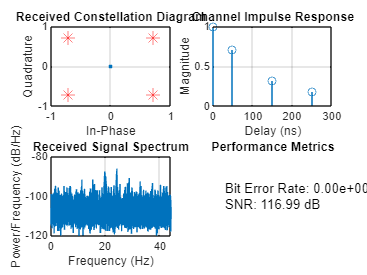


% Plotting
figure('Name', 'Receiver Analysis');

% Plot 1: Received Constellation
subplot(2,2,1);
plot(real(rxSignal(:)), imag(rxSignal(:)), '.');
hold on;
plot(real(symbolMapping), imag(symbolMapping), 'r*', 'MarkerSize', 10);
title('Received Constellation Diagram');
xlabel('In-Phase');
ylabel('Quadrature');
grid on;

% Plot 2: Channel Impulse Response
subplot(2,2,2);
stem(pathDelays*1e9, 10.^(pathGains/20));
title('Channel Impulse Response');
xlabel('Delay (ns)');
ylabel('Magnitude');
grid on;

% Plot 3: Signal Spectrum
subplot(2,2,3);
pwelch(rxSignal(:), [], [], [], fs);
title('Received Signal Spectrum');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

% Plot 4: Error Analysis
subplot(2,2,4);
text(0.1, 0.6, sprintf('Bit Error Rate: %.2e', ber));
text(0.1, 0.4, sprintf('SNR: %.2f dB', 10*log10(txPower/noiseVar)));
title('Performance Metrics');
axis off;


% Display reception parameters
fprintf('\nReception Parameters:\n');


Reception Parameters:


fprintf('Path Loss: %.2f dB\n', pathLoss);

Path Loss: 60.05 dB


fprintf('Shadowing: %.2f dB\n', 20*log10(shadowing));

Shadowing: -0.43 dB


fprintf('SNR: %.2f dB\n', 10*log10(txPower/noiseVar));

SNR: 116.99 dB


fprintf('BER: %.2e\n', ber);

BER: 0.00e+00
